joints = {
    % θ, d, a, α
    {struct('value', 0, 'variable', true, 'type', 'rotation'), 1, 0, -pi/2}, ...
    {struct('value', 0, 'variable', true, 'type', 'rotation'), 0, 1, 0}, ...
    {struct('value', pi/2, 'variable', true, 'type', 'rotation'), 0, 0, pi/2}, ...
    {struct('value', 0, 'variable', true, 'type', 'rotation'), 1, 0, pi/2}, ...
     {0,0,0,struct('value', 0, 'variable', true, 'type', 'rotation')}, ...
    {struct('value', 0, 'variable', true, 'type', 'rotation'), 0, 0, -pi/2}, ...
    {struct('value', 0, 'variable', true, 'type', 'rotation'), 1, 0, 0}, ...
};

dh_table = create_dh_table(joints);
display_dh_table(dh_table);


=== DH Table Information ===
Number of joints: 7
Number of variable parameters: 7

Joint |   θ   |   d   |   a   |   α   |
------|-------|-------|-------|-------|
  1   |  θ1*  | 1.00  | 0.00  | -1.57 |
  2   |  θ2*  | 0.00  | 1.00  | 0.00  |
  3   |  θ3*  | 0.00  | 0.00  | 1.57  |
  4   |  θ4*  | 1.00  | 0.00  | 1.57  |
  5   | 0.00  | 0.00  | 0.00  |  α5*  |
  6   |  θ6*  | 0.00  | 0.00  | -1.57 |
  7   |  θ7*  | 1.00  | 0.00  | 0.00  |

=== Variable Parameters ===
θ1: [-6.283, 6.283] (rotation)
θ2: [-6.283, 6.283] (rotation)
θ3: [-6.283, 6.283] (rotation)
θ4: [-6.283, 6.283] (rotation)
α5: [-6.283, 6.283] (rotation)
θ6: [-6.283, 6.283] (rotation)
θ7: [-6.283, 6.283] (rotation)


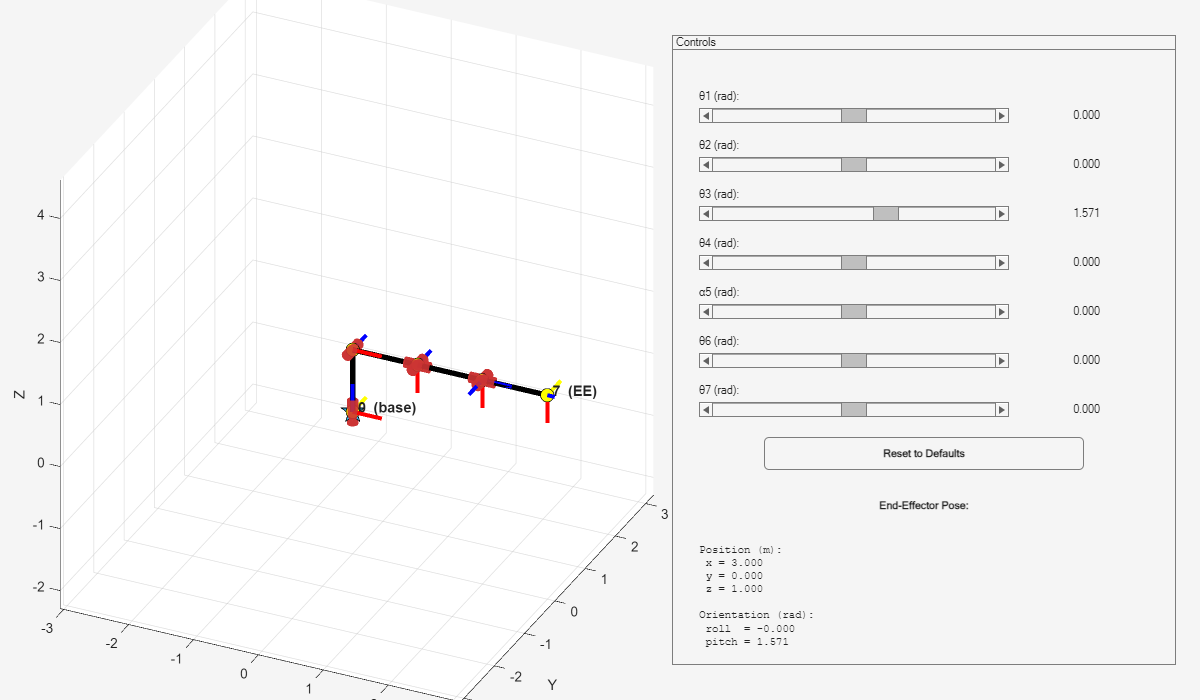

run_dh_visualizer(dh_table,true);